## **ROBOTICA 1**

## **TP N°6: JACOBIANO**

## **Grupo 11**

## Ejercicio 1: considere el robot planar de 2 g.d.l. de la siguiente figura:

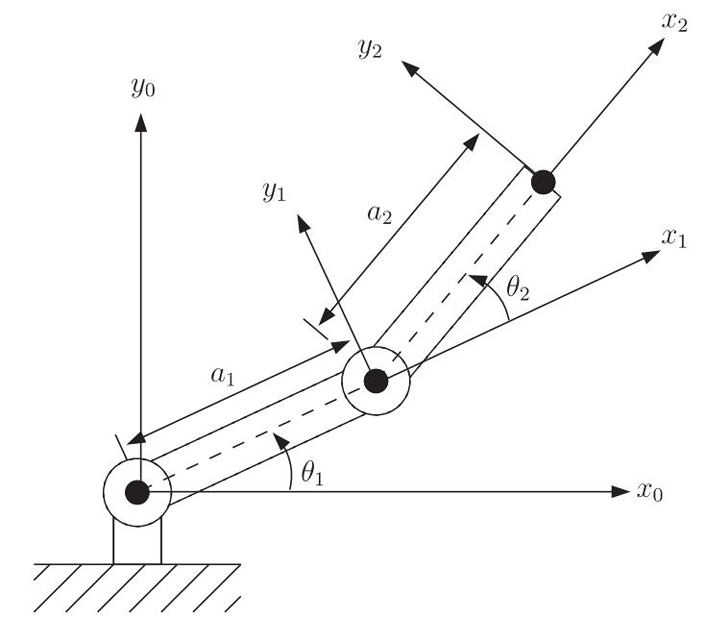

Se puede determinar que la cinemática directa está dada por:


$$x = a_1 cos(\theta_1) + a_2 cos(\theta_1+\theta_2)$$



$$y = a_1 sen(\theta_1) + a_2 cos(\theta_1+\theta_2)$$



$$z = 0$$



$$\alpha
 = 0$$



$$\beta = 0$$



$$\gamma = \theta_1+\theta_2$$


Estas ecuaciones se pueden hallar geométricamente o mediante el análisis de la  transformación ${}^{0}T_2$ que surge de aplicar DH (es necesario convertir ángulos).

Mediante el método geométrico se puede hallar un sistema para la cinemática inversa  correspondiente a la formulación $\overline{q}= f (x,y,z)$:


$$\theta_1= atan2(x-a_2sin(\gamma), x-s_2cos(\gamma))$$



$$\theta_2 =\gamma -\theta_1$$


1. Mediante derivación respecto del tiempo obtenga el Jacobiano del robot que  corresponde a:


$$\dot{p}=J(q)\dot{q}$$


Donde:

- 
$$\dot{p}=[\dot{x}\quad\dot{y}\quad\dot{z}\quad\dot{\alpha}\quad\dot{\beta}\quad\dot{\gamma}]^T$$


- 
$$q = [\theta_1\quad\theta_2]^T$$


2. Calcule la velocidad del extremo $\dot{p}$ , en $m/s$  para $q=[\pi/6\quad\pi/6]$, en 𝑟𝑎𝑑 y $\dot{q}=[0\quad-1]$ en 𝑟𝑎𝑑/𝑠. Suponga longitud de eslabón unitaria. Observe el gráfico del robot  e interprete los resultados.

3. Trabaje solo con las coordenadas X-Y (primeras 2 filas del $J$) y verifique mediante la  inversa algebraica que $\dot{q} = J^{-1}(q)\dot{p}$ se cumple.

## Ejercicio 2: halle el Jacobiano en forma general de los 3 robots siguientes: 

1.

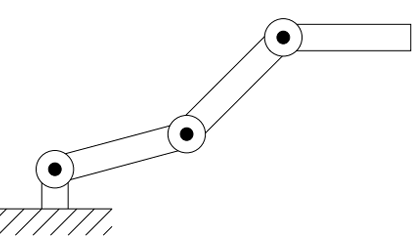

2.

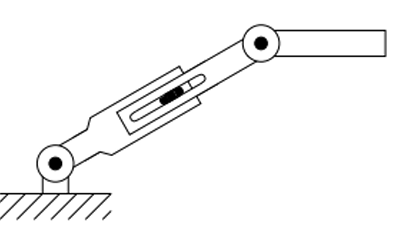

3.

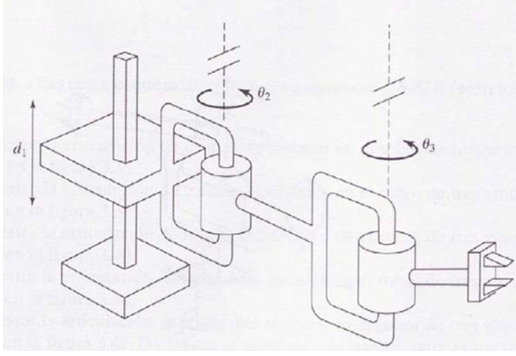

## Ejercicio 3: el siguiente código de ejemplo se puede utilizar para obtener el Jacobiano del  ejercicio 1 de forma general. Haga los cambios necesarios para verificar los resultados del  ejercicio 2. Tenga en cuenta que con las identidades trigonométricas se puede cambiar  radicalmente una misma expresión.

syms q1 q2 a1 a2 real 
q = [q1 q2]; 
dh = [0,0,a1,0,0; 
0,0,a2,0,0]; 
R = SerialLink(dh); 
J = simplify(R.jacob0(q)); 
disp(J)

$$\left(\begin{array}{cc} -a_{2}\,\sin\left(q_{1}+q_{2}\right)-a_{1}\,\sin\left(q_{1}\right) & -a_{2}\,\sin\left(q_{1}+q_{2}\right)\\ a_{2}\,\cos\left(q_{1}+q_{2}\right)+a_{1}\,\cos\left(q_{1}\right) & a_{2}\,\cos\left(q_{1}+q_{2}\right)\\ 0 & 0\\ 0 & 0\\ 0 & 0\\ 1 & 1 \end{array}\right)$$

## Ejercicio 4: agregando el código siguiente al código anterior, se puede observar una expresión  simplificada del determinante del Jacobiano del mismo robot. Es importante recordar que una  matriz cuadrada tiene inversa únicamente si su determinante es distinto de cero.

- 1. Determine para qué valores de $q = [\theta_1\quad\theta_2]^T$ será cero el determinante.

- 2. Interprete qué tienen de particular las soluciones del punto anterior.

## Ejercicio 5:  trabaje con el primer robot del ejercicio 2: 

1) Adapte el código anterior para analizar el Jacobiano simbólico y halle la expresión del  determinante. ¿Puede aplicar los puntos 1 y 2 del ejercicio anterior? 

2) Trabaje numéricamente con longitud de eslabón 1m, 0.8m y 0.6m. Calcule el Jacobiano  y su determinante para $q=[\pi/6\quad\pi/6]$, en 𝑟𝑎𝑑. Verifique que el determinante  es cero. Verifique que el rango de la matriz es menor que los g.d.l. del robot (función  “rank”). Ejecute la función “jsingu(J)” e interprete y relacione el resultado con el robot  del ejercicio 1.

3) Para la posición articular anterior:  

a. Calcule la velocidad articular requerida para lograr las siguientes velocidades  cartesianas en el extremo operativo:$v=[1\quad0\quad0]$ en 𝑚/𝑠. Use el jacobiano  reducido.

b. ¿Por qué existe inversa?

c. ¿Cuál es el número de condición del jacobiano reducido?

d. Asuma que $q_2$ no es cero, sino que está cerca: $q_2 = 0,001$. ¿Cuánto valen las  velocidades articulares para lograr el mismo $v$? 

e. ¿Cuánto valen el determinante y el número de condición del jacobiano en este  caso?

f.  ¿Qué conclusión puede sacar sobre la proximidad del punto singular?

# Ejercicio TF (obligatorio): trabaje con su robot:

Trate de hallar el jacobiano y el determinante simbólico de su robot.  Intente determinar los puntos singulares a partir del determinante simbólico. En caso de que  no se puedan calcular (expresiones muy extensas), identifique al menos 3 mediante  observaciones y análisis, y verifique que el determinante sea nulo en esos casos.  Estudie si en la aplicación elegida se trabajará en las proximidades de algún punto singular.

Debido a que nuestro robot presenta una muñeca esferica, podemos realizar el desacople de del jacobiano para velocidades lineales y angulares, simplificando el calculo del jacobiano y su determinante. 

clc; clear; close all

syms q1 q2 q3 q4 q5 q6 real
q = [q1 q2 q3 q4 q5 q6];

dh = [
    q1  0.283  0.000 -pi/2  0;
    q2  0.000  0.398  0.000 0;
    q3  0.000  0.213  0.000 0;
    q4  0.000  0.000  pi/2  0;
    q5  0.000  0.000  pi/2  0;
    q6  0.166  0.000  0.000 0];

R = SerialLink(dh);

R.base = eye(4);
R.tool = eye(4);
R.offset = [0 0 0 0 0 0];

R.tool = transl(0,0,-0.166); 
J = R.jacob0(q);
disp(simplify(J));

$$\begin{array}{l} \left(\begin{array}{cccccc} -\frac{\sin\left(q_{1}\right)\,\sigma_{4}}{1000} & -\frac{\cos\left(q_{1}\right)\,\sigma_{1}}{1000} & -\frac{213\,\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right)}{1000} & 0 & 0 & 0\\ \frac{\cos\left(q_{1}\right)\,\sigma_{4}}{1000} & -\frac{\sin\left(q_{1}\right)\,\sigma_{1}}{1000} & -\frac{213\,\sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right)}{1000} & 0 & 0 & 0\\ 0 & -\frac{\sigma_{5}}{1000}-\frac{199\,\cos\left(q_{2}\right)}{500} & -\frac{\sigma_{5}}{1000} & 0 & 0 & 0\\ 0 & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right) & -\sin\left(q_{1}\right) & \sigma_{2}\,\cos\left(q_{1}\right) & \cos\left(q_{5}\right)\,\sin\left(q_{1}\right)+\sigma_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{5}\right)\\ 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \cos\left(q_{1}\right) & \sigma_{2}\,\sin\left(q_{1}\right) & \sigma_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{5}\right)-\cos\left(q_{1}\right)\,\cos\left(q_{5}\right)\\ 1 & 0 & 0 & 0 & \sigma_{3} & -\sigma_{2}\,\sin\left(q_{5}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=213\,\sin\left(q_{2}+q_{3}\right)+398\,\sin\left(q_{2}\right)\\ \sigma_{2}=\sin\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{3}=\cos\left(q_{2}+q_{3}+q_{4}\right)\\ \sigma_{4}=\sigma_{5}+398\,\cos\left(q_{2}\right)\\ \sigma_{5}=213\,\cos\left(q_{2}+q_{3}\right) \end{array}$$

    Jv = J(1:3,1:3);
    Jw = J(4:6,4:6);

    detJ_arm = det(Jv);
    detJ_wrist = det(Jw);

    detJ_arm   = simplify(detJ_arm);
    detJ_wrist = simplify(detJ_wrist);

    detJ_fact = simplify(detJ_arm * detJ_wrist);

    disp(simplify(detJ_fact))

$$\sin\left(q_{5}\right)\,\left(\frac{9028431\,\sin\left(q_{2}\right)\,{\cos\left(q_{3}\right)}^{2}}{500000000}+\frac{9028431\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)\,\cos\left(q_{3}\right)}{500000000}-\frac{9028431\,\sin\left(q_{2}\right)}{500000000}+\frac{8435013\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)}{250000000}\right)$$

Analizando esta formula del determinante del Jacobiano, podemos ver 3 casos a simple vista donde este resulta igual 0;

- q5 = 0º/180º                            (Caso 1)

- q2 = 0º/180º y q3 = 0º/180º     (Caso 2)

- q2 = 90°/-90° y q3 = 0°/180°   (Caso 3)

Debido a los limites articulares, solamente los valores 0º y 90° son posibles de alcanzar, por lo que los valores de -90° y 180° se descartan. 

Estos 3 casos de puntos singulares corresponden a la muñeca completamente extendida (Caso 1), el brazo completamente extendido (Caso 2) y el brazo completamente extendido con la muñeca sobre el origen de coordenadas (Caso 3). Se puede observar además, que q1, q4 y q6 no influyen sobre el valor del Jacobiano, por lo que su modificación no puede generar puntos singulares.

Ademas, se presentan casos adicionales donde la muñeca se ubica por encima del origen de coordenadas de la base, pero el brazo no esta completamente extendido. Para visualizarlo, utilizamos la herramienta .teach() del toolbox para posicionar la muñeca del robot sobre el origen de coordenadas de la base, sabiendo que esto tambien es un caso particular. Visualmente se obtuvieron varias posibilidades, utilizaremos q2=65º , q3=80º y q5=70º (Este ultimo cercano a 90º para evitar el primer caso). Calculando el determinante con la formula obtenida previamente en este caso, se obtiene:

q2= 65 *pi/180;
q3= 80 *pi/180;
q5= 70 *pi/180;

det = sin(q5)*((9028431*sin(q2)*cos(q3)^2)/500000000 + (9028431*cos(q2)*sin(q3)*cos(q3))/500000000 - (9028431*sin(q2))/500000000 + (8435013*cos(q2)*sin(q3))/250000000)

det = -4.9246e-04

Este valor es muy cercano a cero, lo que nos muestra que es un punto singular (Caso 4)

Visualmente viendo las singularidades tenemos:

- Caso 1 (Utilizamos offset en q5 de 90º, por lo que para el punto singular se coloca en -90º)

    Eje z4 y z6 estan alineados, y la variacion de sus parametros producen el mismo movimiento (Perdida de un grado de libertad)

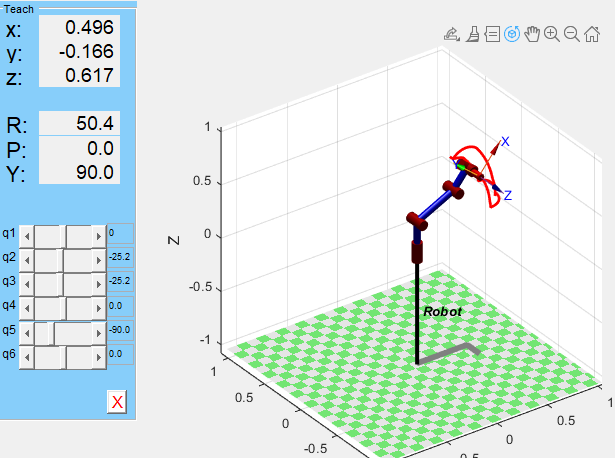

- Caso 2 (Brazo completamente estirado)

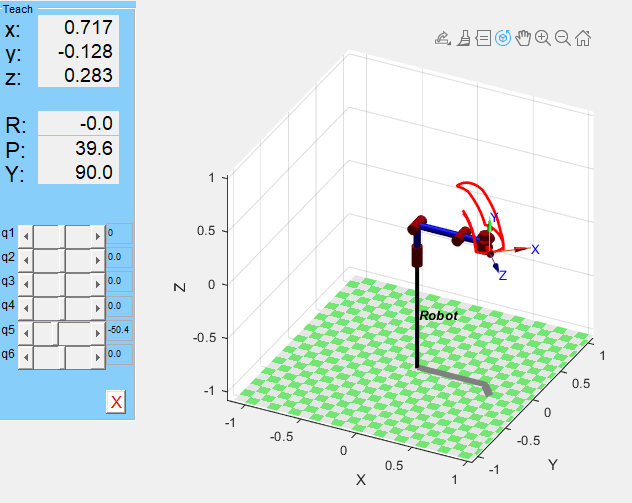

- Caso 3 (Brazo extendido y muñeca sobre origen de coordenadas de la base)

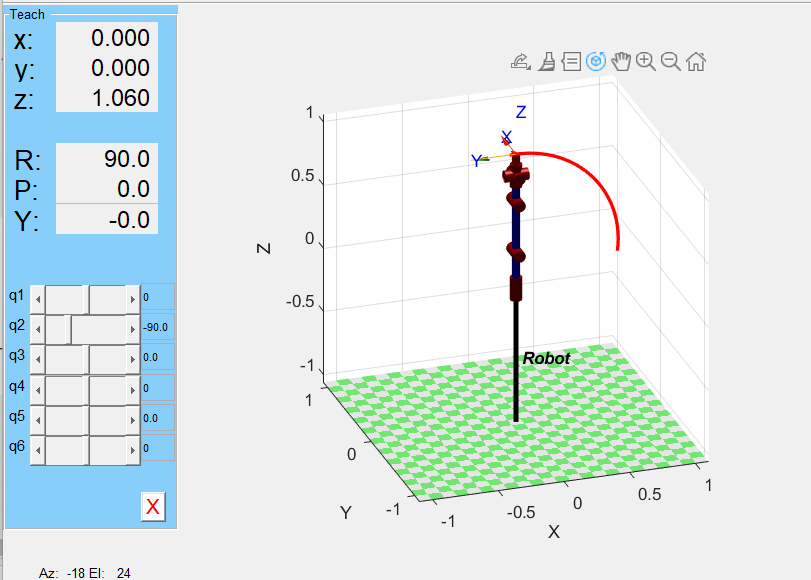

- Caso 4 (Muñeca sobre origen de coordenadas de la base)

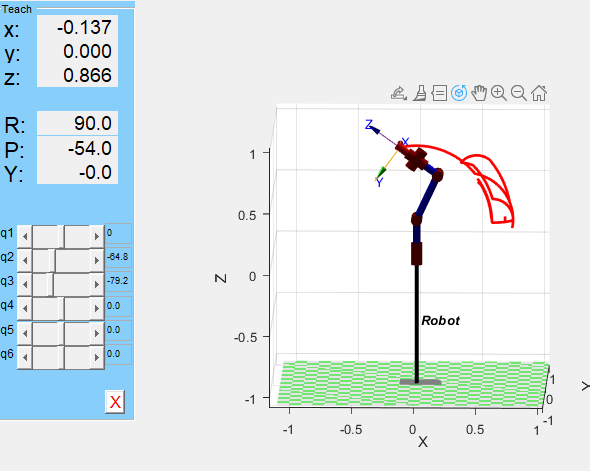

De estos 4 casos, el mas problematico para el uso del robot pueden llegar a ser el caso 2 trabajando sobre piezas demasiado grandes, y el caso 1 si se fuerza afuera de los limites articulares de la muñeca, pero son extremos que pueden evitarse con facilidad, por lo que no deberian presentar problemas para el funcionamiento normal del robot.